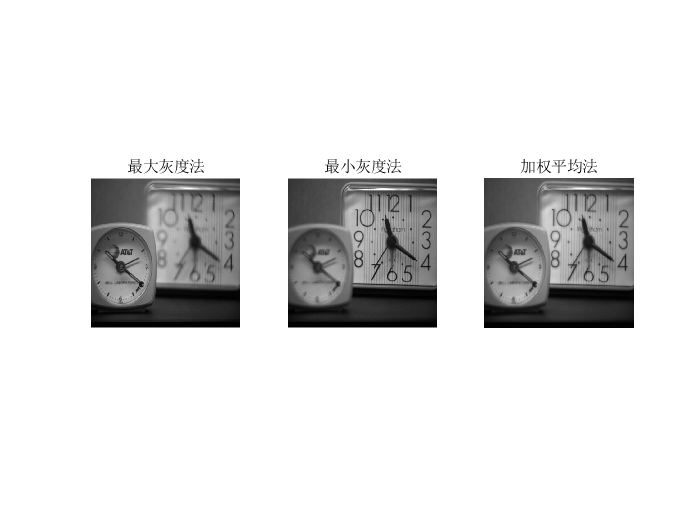

I1 = imread("左聚焦图像.bmp");
I2 = imread("右聚焦图像.bmp");
if size(I1,3) == 3
    I1 = rgb2gray(I1);
end
if size(I2,3) == 3
    I2 = rgb2gray(I2);
end
I1 = double(I1);
I2 = double(I2);
res1 = I1.*(I1>=I2) + I2.*(I2>I1);
res2 = I1.*(I1<=I2) + I2.*(I2<I1);
weight = 0.5;
res3 = weight*I1 + (1-weight)*I2;
figure;
subplot(131),imshow(I1,[]),title('最大灰度法');
subplot(132),imshow(I2,[]),title('最小灰度法');
subplot(133),imshow(res,[]),title('加权平均法');